clear; clc;
load('..\ECG_with_noise.mat');

Butterworth Low pass 

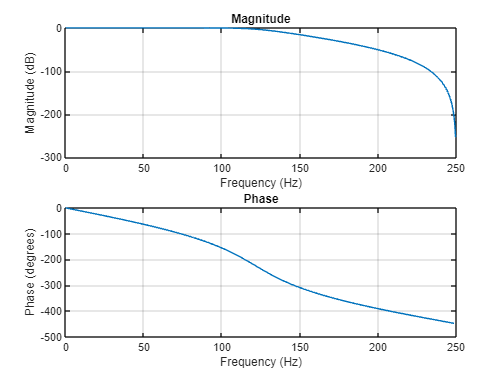

fs = 500;  
T = 1/fs; 

fc_low = 121.582;
% order_low = 61;
order_low = 5;

[b_low,a_low] = butter(order_low,2*fc_low/fs,"low");

freqz(b_low,a_low,[],fs)

% fvtool(b_low,a_low,'Fs',fs);

Butterworth High pass

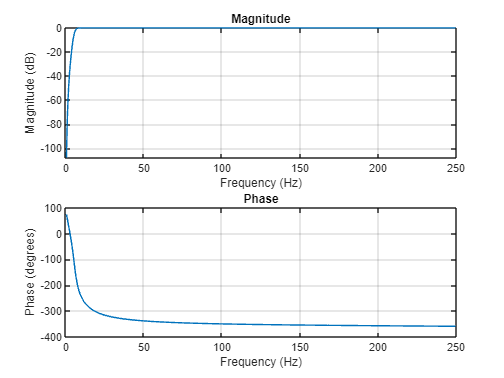

fc_high = 5.85;
order_high = 5;

[b_high,a_high] = butter(order_high,2*fc_high/fs,"high");

freqz(b_high,a_high,[],fs)

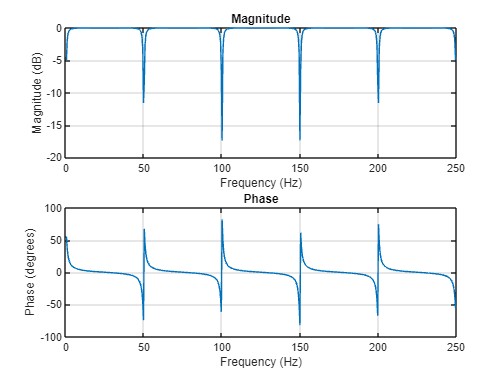

fo_comb = 50;
q = 35;
bw = (fo_comb/(fs/2))/q;
[b_comb,a_comb] = iircomb(fs/fo_comb,bw,'notch'); % Note type flag 'notch'
freqz(b_comb,a_comb,[],fs)

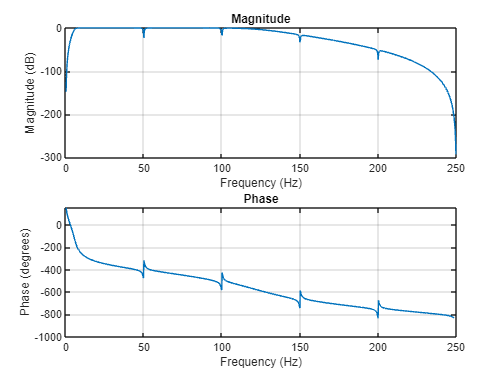

combined_numerator = conv(conv(b_low, b_high), b_comb);
combined_denominator = conv(conv(a_low, a_high), a_comb);

freqz(combined_numerator,combined_denominator,1024,fs); 

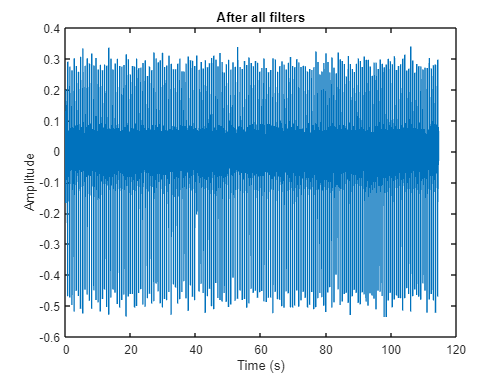

num_points = size(nECG, 2);
time_axis = linspace(0, T * (num_points-1), num_points); 

filtered_signal = filter(combined_numerator,combined_denominator,nECG);
group_delay = round(mean(grpdelay(combined_numerator,combined_denominator)));
filtered_signal(1:group_delay) = [];

plot(time_axis(1:end-group_delay), filtered_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('After all filters');

forward_backward_filtered_signal = filter(combined_numerator,combined_denominator,nECG);
group_delay = round(mean(grpdelay(combined_numerator,combined_denominator)));
forward_backward_filtered_signal(1:group_delay) = [];

plot(time_axis(1:end-group_delay), forward_backward_filtered_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('After all filters');